# MATLAB ASSIGNMENT 2 | EE798L

### 231040059

clc;
clear ;
close all;

%declaring of constants.
N = 20; M = 40; D0 = 7;
noise_var = -20:5:0; %in db.
noise_var_linear = 10.^(noise_var./10); %in linear scale.
NMSE = zeros(length(noise_var),1);

#### 3. Generating the values of 't'   AND

#### 4. Applying SBL for regression.

for i = 1:length(noise_var)
    nmse = 0;

    %for each noise variance, we are finding average NMSE
    %of 100 realisations of weights.

    for j = 1:100

        %generate_t function computes PHI, w, noise samples(epsilon) & t.
        %please refer to "generate_t.m" function file.
        [t, w, PHI, epsilon] = generate_t(M, N, D0, noise_var_linear(i));

        alph = 100*ones(M,1); %alpha_i's are initialised with 100's.

        %compute_params function computes Wmp i.e., mu and SIGMA of
        %posterior of weights.
        [mu, SIGMA] = compute_params(t, alph, noise_var_linear(i), PHI);

        nmse = nmse + ( norm(mu - w)/norm(w) )^2;
    end
    disp("-------------------------------------------------------")
    disp(["weights:", num2str(mu')])

    NMSE(i) = nmse/100; %average NMSE for a given noise variance.
    disp(["noise variance: ", num2str(noise_var_linear(i)), " NMSE: ", num2str(NMSE(i))]);
end

-------------------------------------------------------


    "weights:"    "8.8697e-08  4.4461e-14 -0.00023393 -3.2914e-10  1.5811e-07 -9.9333e-11  0.00018019  2.2648e-06    0.037512    0.050947 -3.1114e-07  2.7204e-06  -0.0095493  1.6655e-07 -0.00045462 -9.4462e-07    -0.12747  -5.073e-07   0.0050462  1.2375e-09  7.9079e-09 -4.0364e-06 -5.0181e-06   2.575e-08  5.7933e-14  -0.0069713 -6.7439e-10  5.4207e-07    -0.19411 -2.8666e-06  0.00041467    0.023777    0.088879    0.056495  -0.0044944  6.3164e-09  3.5429e-05     0.29685   -0.032485    0.035818"



    "noise variance: "    "0.01"    " NMSE: "    "0.40139"



-------------------------------------------------------


    "weights:"    "0.0002183   0.0012043  -3.775e-11  2.6501e-05 -3.4145e-12  7.5761e-08     0.23153  0.00039035    -0.19581    0.044393  0.00084827  9.5923e-11 -0.00031903 -7.2332e-11 -1.2447e-15    -0.19175     0.11053 -3.0737e-05  7.3634e-10 -9.8193e-10  2.8775e-10     0.10677   -0.084773  2.9147e-11 -2.5277e-20  1.3921e-09 -3.7985e-08  1.3288e-09  8.2421e-06    0.098582 -0.00020843  2.5806e-06  1.7159e-10  6.6319e-13  -0.0041578 -2.4582e-07 -0.00067868  3.0831e-05  5.2241e-10 -1.3849e-09"



    "noise variance: "    "0.031623"    " NMSE: "    "0.3948"



-------------------------------------------------------


    "weights:"    "3.9191e-22 -8.7111e-08   -0.039648  1.8591e-08     -0.0116    -0.50648 -7.2821e-16   0.0032036  4.4058e-08  4.0433e-06 -0.00012194    0.043575 -2.0594e-08  2.4516e-09     0.42482  1.1729e-13 -0.00028417  3.3591e-18 -1.6308e-16    -0.18088  -0.0043908    0.034305    -0.23365  4.1224e-13  1.7584e-13 -1.6486e-09 -0.00091331  6.8138e-11  1.1913e-07  2.4001e-07  3.9293e-13  4.0799e-07 -4.9487e-12     0.18227 -2.3345e-15    -0.49121  4.7375e-11 -1.5792e-19  2.1041e-11 -5.3967e-09"



    "noise variance: "    "0.1"    " NMSE: "    "0.43359"



-------------------------------------------------------


    "weights:"    "3.0223e-07 -2.0024e-10 -5.4768e-09 -0.00071983  -0.0030525   0.0014503  1.6786e-16  4.2552e-09 -4.3095e-16 -8.6148e-07 -1.4647e-13 -3.8747e-09    -0.16286    0.017603     0.84428    0.097026  6.5351e-08  -3.823e-07    -0.66294    -0.55909  -0.0010479     -1.4597    0.005054 -3.1189e-05 -4.3252e-05  2.4002e-14  1.6444e-11  1.6663e-07 -1.9842e-08  -0.0031831  6.9357e-11  6.4991e-10 -0.00012607  1.5594e-06  5.1091e-19  4.8088e-15  0.00012417      0.0195   -0.020552 -7.5885e-18"



    "noise variance: "    "0.31623"    " NMSE: "    "0.31091"



-------------------------------------------------------


    "weights:"    "4.9172e-10    -0.68204     0.11265 -4.5203e-07 -2.7932e-06  2.5796e-09   0.0010189  6.6489e-09  6.2605e-10   -0.039349    -0.34851 -6.9381e-06     0.12588  0.00012246  1.6461e-05  2.6915e-09  -1.163e-08 -1.7953e-05  4.0031e-07      -1.837     0.77614   5.919e-12     -1.2236  0.00050035    -0.54749 -2.9677e-12  0.00057302 -4.7253e-14   4.263e-08  0.00021498 -8.0606e-06  9.0075e-06 -4.7954e-07    -0.28992 -6.2759e-13     0.85233   0.0016279  1.1717e-08 -1.5867e-13  0.00034528"



    "noise variance: "    "1"    " NMSE: "    "0.3804"



#### 5. Plotting NMSE vs Noise curve

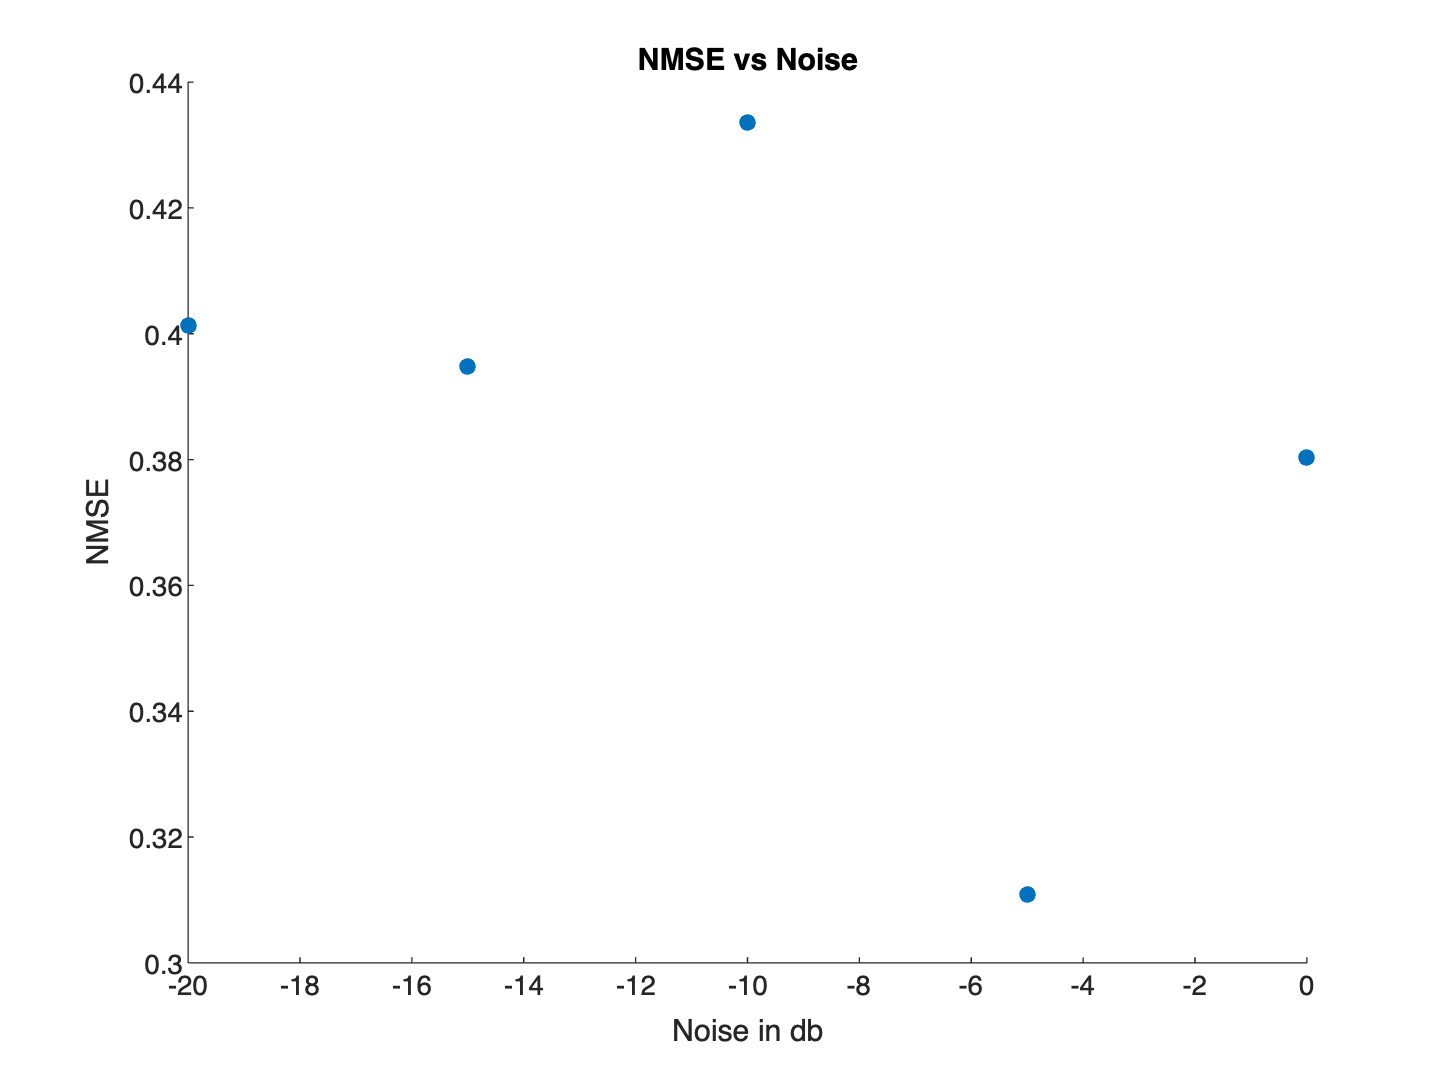

scatter(noise_var, NMSE, 'filled')
xlabel("Noise in db")
ylabel("NMSE")
title("NMSE vs Noise")